# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 7-b. 근 궤적법과 Jury 판별법을 이용한 안정성 판별**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 근 궤적법을 이용한 안정성 판별

Topic 1에서는 근 궤적법(root locus)를 이용한 폐루프 시스템의 안정성 판별법에 대해 살펴보고자 합니다. 연속 시간 플랜트


$$G_p(s)=\frac{0.2}{s^2 + 2s + 2}$$


를 샘플 데이터 제어 환경에서 다음의 이산 시간 제어기


$$C^d(z)=K$$


로 제어하는 상황을 생각해봅시다. 이때 적절한 제어기 이득 $K$를 선정하기 위해, 먼저 연속 시간 플랜트에 대한 펄스 전달함수를 계산합니다.

num_Gp_tf = 0.2;
den_Gp_tf = [1 2 2];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);

T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh')

Gd_tf =
 
  0.003493 z + 0.003057
  ----------------------
  z^2 - 1.605 z + 0.6703
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


이제 `rlocus` 함수를 이용하여 $K$가 0에서부터 $\infty$로 커짐에 따라 폐루프 시스템의 전달함수 $T^d(z)=\frac{KG^d(z)}{1+KG^{d}(z)}$의 극점(pole) 궤적을 그려봅시다.

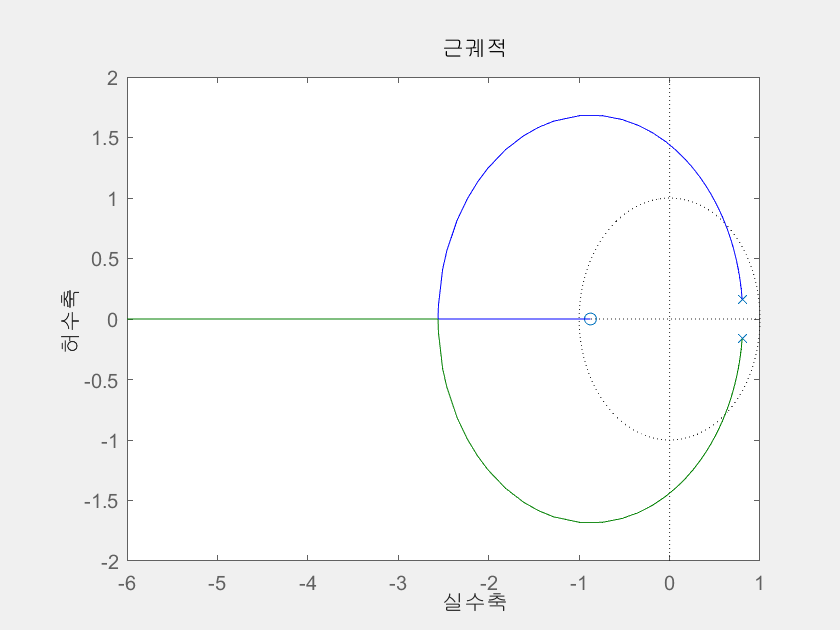

f = figure();
set(f, 'Visible', 'on'); % rlocus 함수의 결과물을 별도의 창으로 띄우기 위해 추가 설정
rlocus(Gd_tf)

이제 외부 창에 띄워진 근 궤적 위의 한 점을 클릭한 후, 단위원에 가장 가까운 위치로 커서를 옮기면 아래의 결과를 얻습니다.

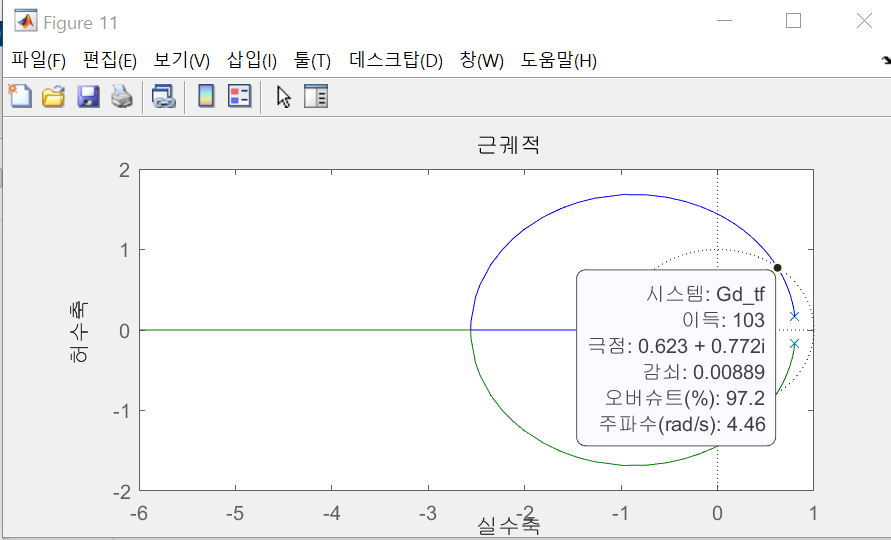

여기서 "이득"은 폐루프 시스템의 극점 위치가 커서 위치와 동일하도록 하는 $K$값을 의미합니다. 

따라서 위의 근궤적을 통해, 


$$0<K<103$$


범위 내의 모든 $K$는 폐루프 시스템을 안정화하게 만듬을 수치적으로 확인할 수 있습니다. 

이를 시각적으로 표현하기 위해, 몇 가지 $K$ 값에 대한 단위 계단 응답을 그려봅시다.

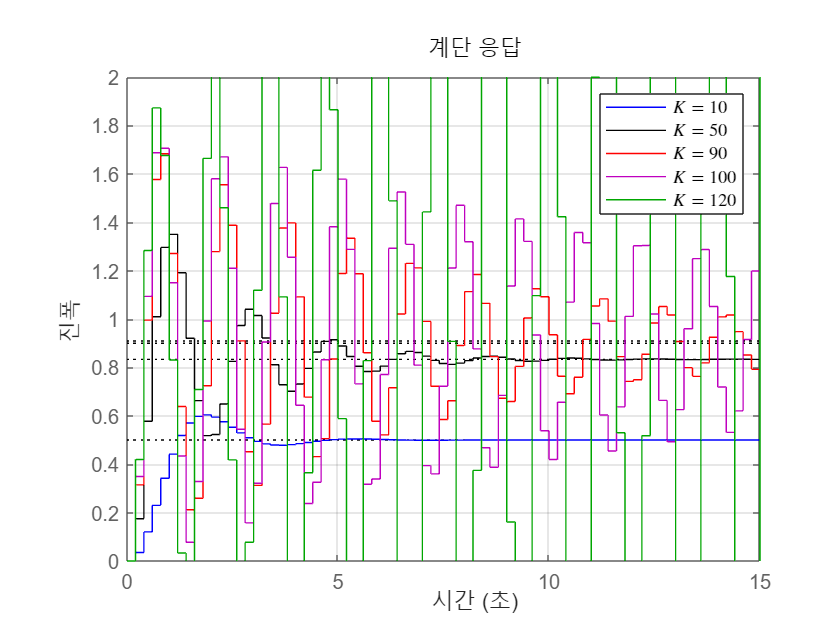

list_K = {10, 50, 90, 100, 120};
length_list_K = 5;
list_Td_tf = cell(length_list_K,1);
list_color = {'b', 'k', 'r', 'm', 'g'};

for idx = 1:length_list_K
    list_Td_tf{idx} = Gd_tf * list_K{idx} / (1 + Gd_tf * list_K{idx});
end

figure();
for idx = 1:length_list_K
    hold on;
    step(list_Td_tf{idx}, list_color{idx});
end
legend('$K=10$', '$K=50$', '$K = 90$', '$K = 100$', '$K = 120$','Interpreter','latex','Location','northeast');
grid on;
xlim([0 15]);
ylim([0 2]);

여기서 유의할 점은 아래와 같습니다. 

- 안정성을 보장하는 범위 내에서 $K$가 커질수록 단위 계단 응답의 정상상태값이 $1$에 근접해집니다. 

- 하지만 $K$를 크게 하여 전체 폐루프 극점이 단위원에 가까워짐에 따라 단위 계단 응답이 더 큰 oscillation을 경험하게 됩니다. 

- 안정성을 보장하는 범위 밖의 $K$를 선정하면 전체 시스템이 불안정해집니다.

따라서 샘플 데이터 시스템에서 만족할만한 정상상태 오차를 얻기 위해서 제어기 이득을 키우는 것은 한계가 있으며, 6장에서 살펴본 시스템 유형을 증가시킬 필요가 있다는 점을 간접적으로 확인할 수 있습니다.

### Topic 2 : Jury의 안정성 판별법을 통한 2차 검증

전체 폐루프 시스템을 안정화시키는 구체적인 $K$의 범위를 얻기 위해, Jury의 안정성 판별법을 적용하여 2차적으로 검증해봅시다.

앞에서 구한 $G^d(z)$를 아래와 같이 표현합시다. 


$$G^d(z)=\frac{n_1 z + n_0}{d_2 z^2 + d_1 z + d_0}$$
 

여기서 분자식과 분모식의 계수에 해당하는 $n_i$와 $d_i$들은 `tfdata` 함수를 이용하여 쉽게 얻을 수 있습니다.

[num_Gd_tf, den_Gd_tf] = tfdata(Gd_tf);
num_Gd_tf = num_Gd_tf{1}

num_Gd_tf =          0    0.0035    0.0031


den_Gd_tf = den_Gd_tf{1}

den_Gd_tf =     1.0000   -1.6048    0.6703


그러면 폐루프 시스템의 안정성을 결정하는 특성 방정식 


$$1+KG^d(z)=0$$


의 해(solution)들은, 아래 식을 만족해야 합니다. 


$$F^d(z):= d_2 z^2 + (d_1 + K n_1) z + (d_0 + K n_0)=0$$


따라서 폐루프 시스템이 안정하기 위해서는, 위에서 정의된 다항식 $F^d(z)$의 해들이 모두 단위원 안에 위치해야 합니다.

syms z K;
Fd = den_Gd_tf(1) * z^2 + (den_Gd_tf(2) + K * num_Gd_tf(2)) * z + (den_Gd_tf(3) + K * num_Gd_tf(3));

Jury의 안정성 판별법에 따르면, 아래 3가지 조건을 모두 만족할 경우 $F^d(z)$의 해들이 모두 단위원 안에 위치합니다.

- 조건 1 : $F^d(1)>0$;

- 조건 2 : $(-1)^2 F^d(-1) = F^d(-1)>0$

- 조건 3 : $|d_0+Kn_0| < d_2$

MATLAB의 symbolic expression을 이용하면, 아래의 3개 항들이 모두 0보다 커야함을 얻습니다.

vpa(subs(Fd,z,1),5) % >0 for Condition 1

$$ans = 0.0065499\,K+0.065499$$

vpa(subs(Fd,z,-1),5) % >0 for Condition 2

$$ans = 3.2751-0.00043666\,K$$

vpa(den_Gd_tf(1) - abs(den_Gd_tf(3) + K * num_Gd_tf(3)),5) % >0 for Condition 3

$$ans = 1.0-1.0\,\left|0.0030566\,K+0.67032\right|$$

이를 정리하면 다음 조건들을 얻습니다.


$$-\frac{0.065499}{0.0065499} = -10< K,\\
K<\frac{3.2751}{0.00043666}\approx 7500.3,\\
-1<0.0030566 K + 0.67032<1$$


여기서 3번째 줄의 두 부등식들은 아래와 같이 정리할 수 있습니다.


$$-546.4634\approx \frac{-1-0.67032}{0.0030566}<K<\frac{1-0.67032}{0.0030566}\approx 107.8584$$


이를 종합해보면, 폐루프 시스템이 안정하기 위해 (양수인) $K$가 만족해야 할 최종 조건은 


$$0<K<107.8584$$


입니다. 

이를 통해 Topic 1에서 수치적으로 계산한 값보다 좀 더 정교하게 $K$의 범위를 계산할 수 있게 됩니다. 

이 범위의 정교함을 확인하기 위해, 경계값인 $107.8684$를 기준으로 5개의 $K$ 값을 선정하고, 이에 대해 단위 계단 응답을 다시 그립니다.

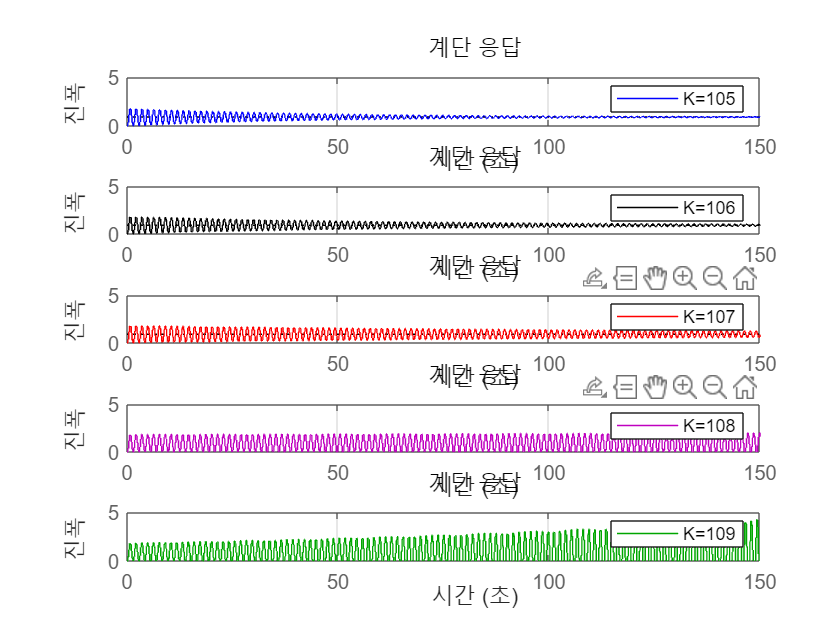

list_K = {105, 106, 107, 108, 109};
length_list_K = 5;
list_Td_tf = cell(length_list_K,1);
list_color = {'b', 'k', 'r', 'm', 'g'};

for idx = 1:length_list_K
    list_Td_tf{idx} = Gd_tf * list_K{idx} / (1 + Gd_tf * list_K{idx});
end

figure();
for idx = 1:length_list_K
    subplot(length_list_K,1,idx)
    step(list_Td_tf{idx}, list_color{idx});   
    legend(append('K=',num2str(list_K{idx})));
    grid on;
    xlim([0 150]);
    ylim([0 5]);
end

시뮬레이션을 통해 $K=108$ 이상의 제어기 이득을 사용하면 전체 시스템을 불안정하게 만듬을 다시 한 번 확인해볼 수 있습니다. 